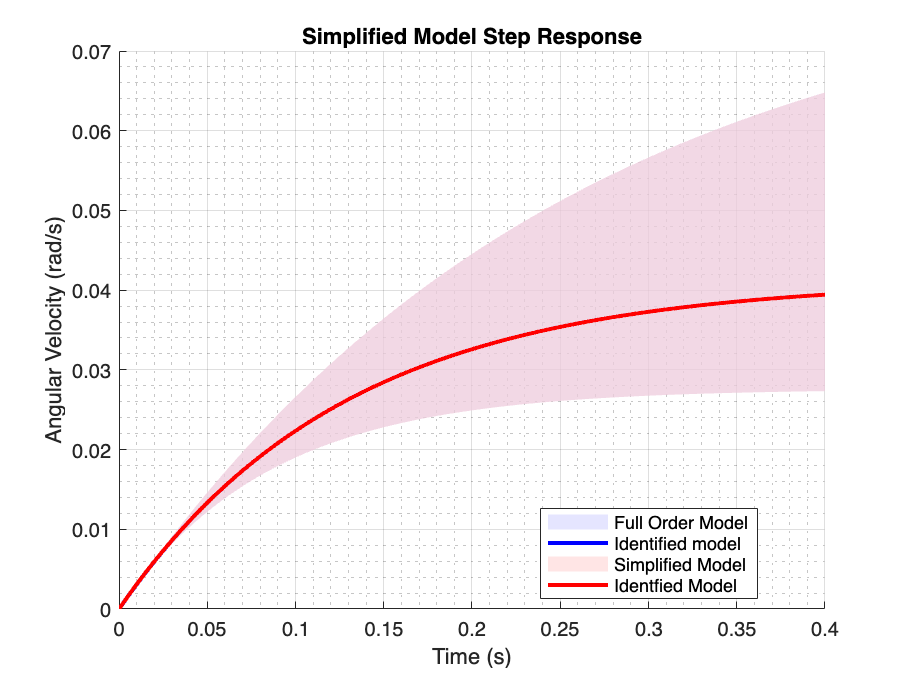

%% Clear workspace and figures
clear; clc; close all;

%% Nominal Parameters
% Inertias and friction
Jr = 3.2284E-5;    % Rotor rotational inertia [Nms^2/rad]
Jg = 3.22E-5;      % Gearbox rotational inertia
Bg = 0.0001;       % Viscous friction [Nms/rad]
Br = 0;            % Additional friction

% DC Motor Manufacturer Parameters 
IStall = 2;
TStall = 0.39;
Inoload = 0.2;
n = 20;

% Derived motor parameters
speedvolt_grad = 0.6594 * n * 2*pi;  % measured in rad/s per volt
Kt = ((IStall - Inoload) / TStall)^-1; % Motor torque constant
Ke = (speedvolt_grad)^-1;             % Motor back-EMF constant
Ra = 2.6;                             % Armature resistance [Ω]
La_nom = 1E-6;                           % Nominal armature inductance [H]
Jeq = Jg + n^2 * Jr;                  % Equivalent inertia
Beq_nom = Bg + n^2 * Br;              % Nominal effective damping

%% Parameter Variations for Sensitivity Analysis
La_values = [0.5E-6, 1E-6, 1.5E-6 ]; % Variation for armature inductance [H]
Beq_values = [0.05, 0.1, 0.15];     % Variation for effective damping [Nms/rad]

% Define nominal indices: La=1 (2nd element), Beq=0.1 (2nd element)
nomLaIndex = 2;
nomBeqIndex = 2;

%% Time vector for simulation
t_end = 0.4;               % Simulation end time (s)
t = linspace(0, t_end, 1000);  % Time vector

%% Create Laplace variable
s = tf('s');

%% Preallocate arrays for storing step responses
numComb = length(La_values) * length(Beq_values);
responses_full = zeros(length(t), numComb);
responses_simp = zeros(length(t), numComb);

% Loop over parameter combinations and compute responses
combIndex = 1;
for i = 1:length(La_values)
    for j = 1:length(Beq_values)
        La = La_values(i);
        Beq = Beq_values(j);
        
        % Full-order model transfer function
        % Denom: (s^2)*(La*Ra) + s*(Ra*Jeq + Beq*La) + (Kt*Ke + Ra*Beq)
        motor_tf = (Kt / n) / ( (s^2)*(La*Ra) + s*(Ra*Jeq + Beq*La) + Kt*Ke + Ra*Beq );
        
        % Simplified (first-order) model transfer function
        % Denom: s*(Ra*Jeq) + (Kt*Ke + Ra*Beq)
        motor_simp_tf = (Kt / n) / ( s*(Ra*Jeq) + Kt*Ke + Ra*Beq );
        
        % Compute step responses
        responses_full(:, combIndex) = step(motor_tf, t);
        responses_simp(:, combIndex) = step(motor_simp_tf, t);
        
        combIndex = combIndex + 1;
    end
end

% Determine the index for the nominal combination (La=1, Beq=0.1)
nom_index = (nomLaIndex-1)*length(Beq_values) + nomBeqIndex;

% Compute the envelope (min and max) across all responses for each time point
min_full = min(responses_full, [], 2);
max_full = max(responses_full, [], 2);
min_simp = min(responses_simp, [], 2);
max_simp = max(responses_simp, [], 2);

%% Plotting the Results

figure;

hold on;
% Create a shaded envelope showing the spread of responses
fill([t, fliplr(t)], [min_full', fliplr(max_full')], [0.8, 0.8, 1], ...
     'FaceAlpha', 0.5, 'EdgeColor', 'none');
% Plot the nominal response as a solid blue line
plot(t, responses_full(:, nom_index), 'b', 'LineWidth', 2);
grid on; grid minor; hold on
fill([t, fliplr(t)], [min_simp', fliplr(max_simp')], [1, 0.8, 0.8], ...
     'FaceAlpha', 0.5, 'EdgeColor', 'none');
plot(t, responses_simp(:, nom_index), 'r', 'LineWidth', 2);
legend("Full Order Model", "Identified model", "Simplified Model", "Identfied Model",'Location','Best'); 

title('DC Motor Open Loop Step Response');
xlabel('Time (s)');
ylabel('Angular Velocity (rad/s)');
grid on; hold off;